# **Fault Insertion Control**

This example shows you how to setup the IO983-02-75-2 I/O module, in order to verify the basic functionality.

The IO983 is a fault insertion module with up to 75 channels and various fault bus options. The switches are either electro-mechanical, suitable for low level signals or MOSFET for higher voltages and currents.

The Simulink model features the [IO983 - Fault Insertion Control](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io98x_fault_insertion_control_v2) block.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO983-02-75-2 I/O module installed

- Connector cable from the I/O module to the terminal board

- 78-pin terminal board

- Ohmmeter

### Test Setup

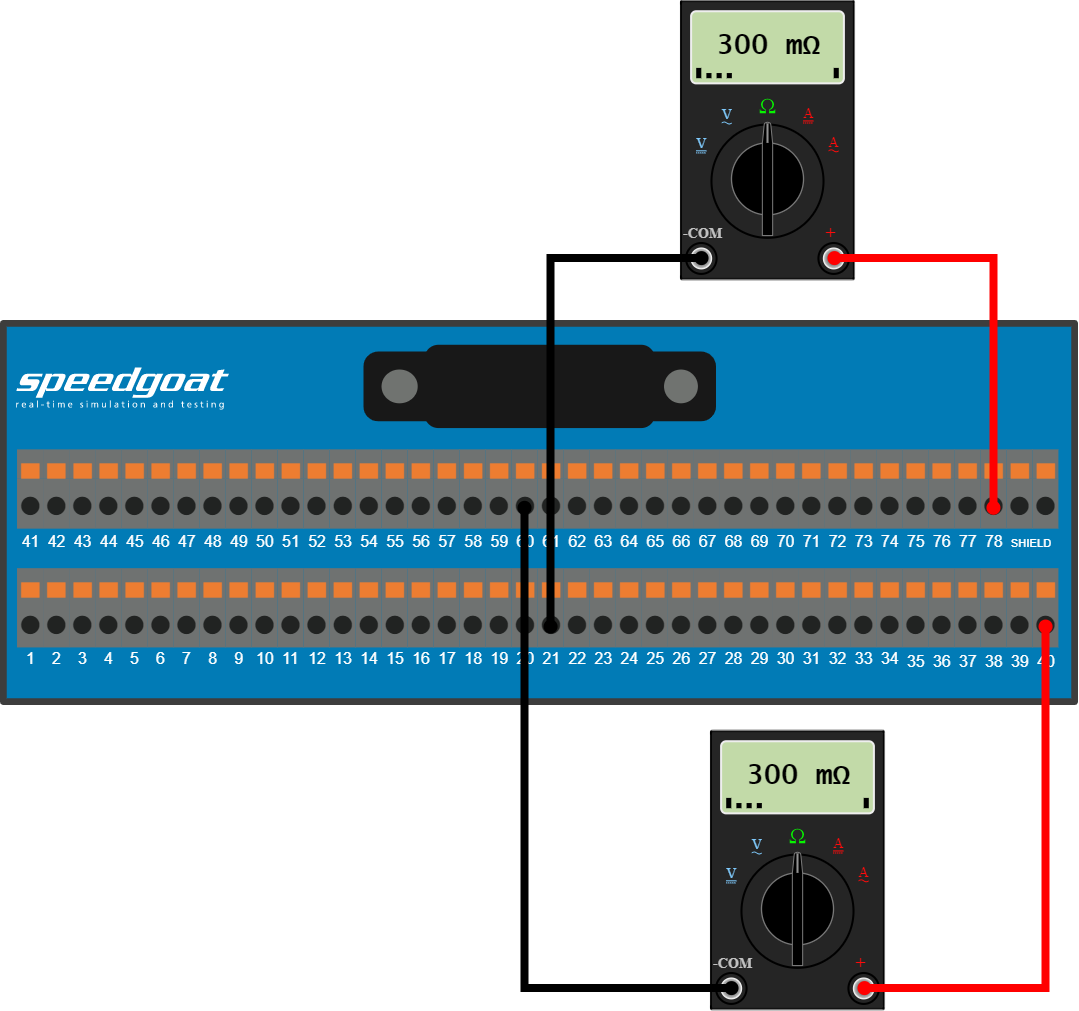

On the terminal board of the I/O module, connect an ohmmeter to one of the two enabled break relay channels or the fault bus connection to check their switch state as shown above. [IO983 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io98x_pin_mapping)

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_FaultInsertionControl';
open_system(modelName);

### Model Description

In the model, a step signal is applied on the break relays of the two enabled channels. It switches the break relays on after 5 seconds of the model run-time. For channel one, the fault bus one and two switches are always on, whereas they are off for channel two. The fault bus connections F1 to F3 and F5 to F7 are sequentialy enabled after each other. This allows to apply different fault scenarios on to the fault bus. 

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

To check whether the switches have changed their state, check the connected scopes. In the BreakRelays scope a step signal with a switching point at 5 seconds must be displayed. In the FaultBus scope, the fault bus connections (F1 to F6) are switched through sequentially. Each  fault bus connection is therefore connected once to the fault bus.

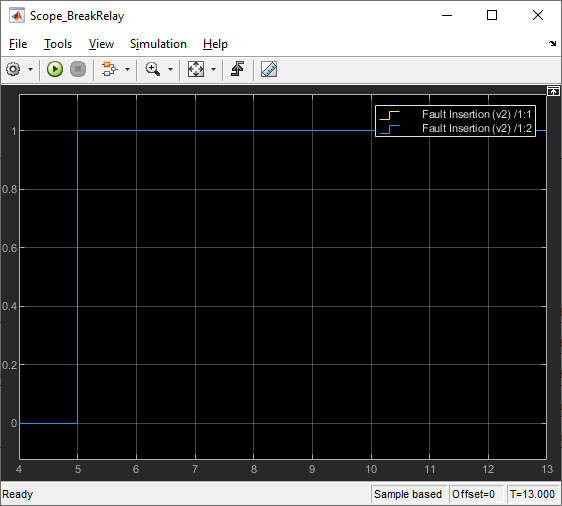

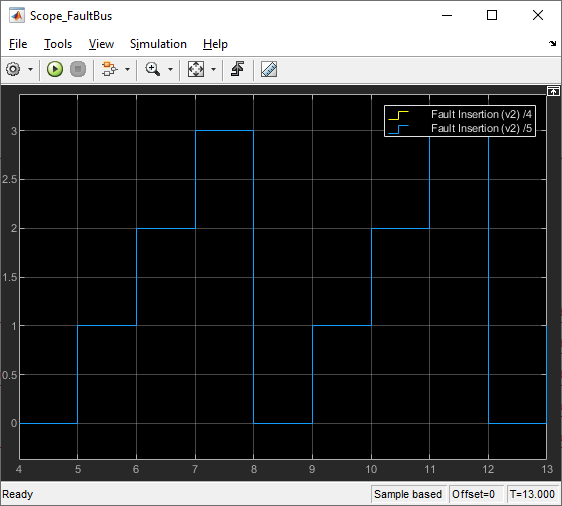

## Additional References

- [IO98x documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io98x)